# Exercise 7.2 - Chirp signals, sampling

## Observations

Since the sampling frequency is not at least twice that of the maximum digital frequency of the chirp, we get aliasing, according to Nyquist's theorem. In fact, we see that after changing the sampling frequency to 2 kHz, that is no longer the case.

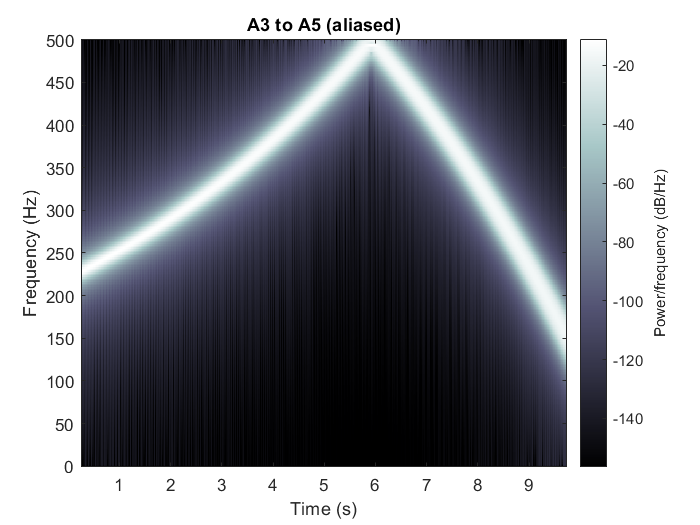

f0 = 220;                       % A3 frequency.
f1 = 880;                       % A5 frequency.
fs_1 = 1000;                    % Sampling frequency #1.
fs_2 = 2000;                    % Sampling frequency #2.
n_1 = 0 : (10 * fs_1) - 1;      % Discrete time samples array.

% Generate the chirp signal.
y = chirp(n_1 / fs_1, f0, 10, f1, 'logarithmic');
sound (y, fs_1);

% Draw its spectrogram.
spectrogram(y, hanning(512), 500, 512, fs_1, 'yaxis');
title('A3 to A5 (aliased)'), colormap bone

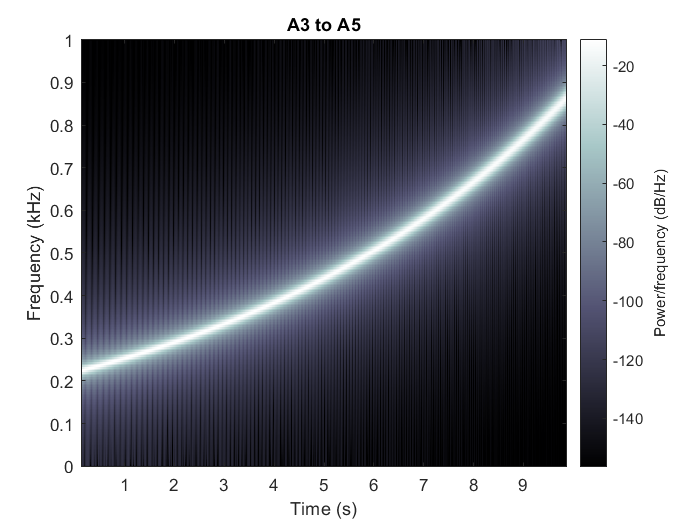


n_2 = 0 : 10 * fs_2;    % Discrete time samples array.
y_2 = chirp(n_2 / fs_2, f0, 10, f1, 'logarithmic');
spectrogram(y_2, hanning(512), 500, 512, fs_2, 'yaxis');
title('A3 to A5')

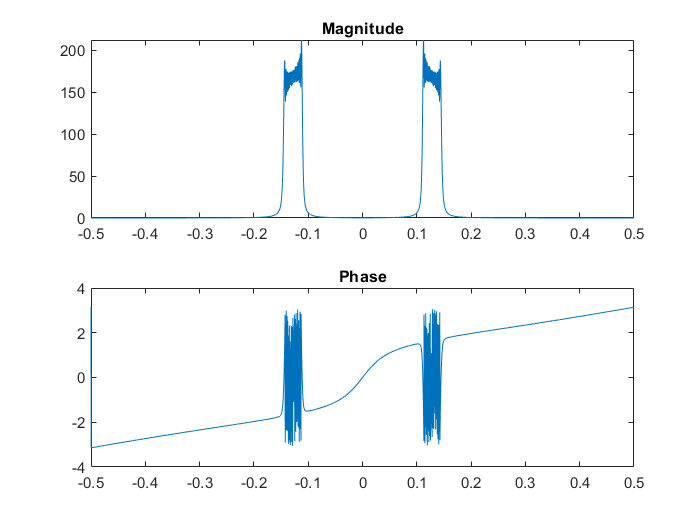


% Fourier Transform.
N = 4096;                                       % # of points.
spectrum = fft(y_2, N);                         % Compute FFT.
spectrumShifted = fftshift(spectrum);           % Shift to the origin.

% Plot of the spectrum (magnitude and phase of the FFT)
f = (0 : (N - 1)) / N - 0.5;    % OX-axis boundaries.
subplot(211), plot(f, abs(spectrumShifted)), title('Magnitude');
subplot(212), plot(f, angle(spectrumShifted)), title('Phase');